## Reading Data

clear 
clc



fid = fopen("CALI.BIN", "rb", 'b');

if (fid ~= 0)
    disp("Open file succeed!");
else 
    disp("Open file failed!");
end

Open file succeed!



ftell(fid)

ans =      0


SAMPLE_POINT = 100000;

head = ftell(fid);

if (head ~= 0)
    fseek(fid, 0,'bof');
end
data_origin = fread(fid, SAMPLE_POINT*4, 'uint8', 'b');

fclose(fid);
data_origin(1:10)

ans =    229
    34
    15
    33
   228
     3
    48
     1
   231
    34



% uint8 -> dec 
% data = dec2bin(s.UserData); 
data = dec2bin(data_origin)

data = 400000×8 char 数组
    '11100101'
    '00100010'
    '00001111'
    '00100001'
    '11100100'
    '00000011'
    '00110000'
    '00000001'
    '11100111'
    '00100010'
    '00001111'
    '00100001'
    '11100101'
    '00000011'
    '00110000'
    '00000001'
    '11100110'
    '00100010'
    '00001111'
    '00100001'
    '11100100'
    '00000011'
    '00110000'
    '00000001'
    '11101000'
    '00000000'
    '00001111'
    '00100001'
    '11100100'
    '00000011'
    '00110000'
    '00000001'
    '11100110'
    '00100010'
    '00001111'
    '00100001'
    '11100011'
    '00000011'
    '00110000'
    '00000001'
    '11100100'
    '00100010'
    '00001111'
    '00100001'
    '11100001'
    '00000011'
    '00110000'
    '00000001'
    '11100110'
    '00100010'
    '00001111'
    '00100001'
    '11001000'
    '00000010'
    '00110000'
    '00000001'
    '11100110'
    '00100010'
    '00001111'
    '00100001'
    '11100101'
    '00000011'
    '00110000'
    '00000001'
    '11100011'
 


% d1 = data(:, 25:32)
% d2 = data(:, 17:24)
% d3 = data(:, 9:16)
% d4 = data(:, 1:8)

data_sorted = zeros(SAMPLE_POINT*4,8);
for i=1:SAMPLE_POINT*4
    switch mod(i,4)
        case 1
            data_sorted(i,:) = data(floor(i/4)*4+4, :);
        case 2
            data_sorted(i,:) = data(floor(i/4)*4+3, :);
        case 3
            data_sorted(i,:) = data(floor(i/4)*4+2, :);
        otherwise
            data_sorted(i,:) = data(i-3,:);
    end
end
data_sorted = char(data_sorted)

data_sorted = 400000×8 char 数组
    '00100001'
    '00001111'
    '00100010'
    '11100101'
    '00000001'
    '00110000'
    '00000011'
    '11100100'
    '00100001'
    '00001111'
    '00100010'
    '11100111'
    '00000001'
    '00110000'
    '00000011'
    '11100101'
    '00100001'
    '00001111'
    '00100010'
    '11100110'
    '00000001'
    '00110000'
    '00000011'
    '11100100'
    '00100001'
    '00001111'
    '00000000'
    '11101000'
    '00000001'
    '00110000'
    '00000011'
    '11100100'
    '00100001'
    '00001111'
    '00100010'
    '11100110'
    '00000001'
    '00110000'
    '00000011'
    '11100011'
    '00100001'
    '00001111'
    '00100010'
    '11100100'
    '00000001'
    '00110000'
    '00000011'
    '11100001'
    '00100001'
    '00001111'
    '00100010'
    '11100110'
    '00000001'
    '00110000'
    '00000010'
    '11001000'
    '00100001'
    '00001111'
    '00100010'
    '11100110'
    '00000001'
    '00110000'
    '00000011'
    '11100101'
    '0010

data_tag = data_sorted(:,1:2);

if (sum(mod(find(data_tag=='11'), 4)) > 0 )
    disp("Data Missing!");
    index = find(data_tag == '11');
    index_mod = mod(index, 4);
    fprintf("Missing data occured at %d sampled point;\n",find(index_mod ~= 0, 5))
    
else
    disp("Data Right!");
end

Data Right!


data_sign = str2num(data_sorted(:,3));
data_value = data_sorted(:,4:end);

data_sign(data_sign==1) = -1;
data_sign(data_sign==0) = 1;
data_value = bin2dec(data_value) .* data_sign

data_value =     -1
    15
    -2
    -5
     1
   -16
     3
    -4
    -1
    15


data_N4 = reshape(data_value, [4, SAMPLE_POINT])'

data_N4 =     -1    15    -2    -5
     1   -16     3    -4
    -1    15    -2    -7
     1   -16     3    -5
    -1    15    -2    -6
     1   -16     3    -4
    -1    15     0    -8
     1   -16     3    -4
    -1    15    -2    -6
     1   -16     3    -3


## Calibration

% ~~~~~~~~~~~~~~~ test environment ~~~~~~~~~~~~~~~
% clk_50M = 50E6;
% clk_adc = clk_50M / 5_000 ;
% fs = clk_adc / 50;

Vref = 1.8;
N_SUB = 5;
LSB_SUB = 1.8 / 2^N_SUB;

% ~~~~~~~~~~~~~~~ calculate gain ~~~~~~~~~~~~~~~
% gain = zeros(1,SAMPLE_POINT);
% for i = 1:SAMPLE_POINT
%     if (mod(i, 2) == 0)
%         gain_temp = Newton_Calib(-1*data_N4(i,2:end), 10);
%         gain(i) = gain_temp(10);
%     else 
%         gain_temp = Newton_Calib(data_N4(i,2:end), 10);
%         gain(i) = gain_temp(10);
%     end
% end

% Newton_Calib(data_N4(1,2:end) - data_N4(2,2:end), 10)
gain = deltaGain(data_N4(:,2:end), 10)

gain =   15.334846374300870
  15.332696083726690
  15.332696083726690
  15.394120634171388
  15.330544579227878
  15.330544579227878
  15.339873048069668
  15.334846374300870
  15.346322000618613
  15.341289980417331



% gain = abs(gain);
% GAIN = mean(gain);
% % ~~~~~~~~~~~~~~~ display result ~~~~~~~~~~~~~~~
% figure
% hold on;
% plot(gain);
% % plot(gain_plus);
% plot(ones([1,SAMPLE_POINT/2])*GAIN)
% % plot(ones([1,SAMPLE_POINT/2])*GAIN_PLUS)
% hold off;
% xlim([0, SAMPLE_POINT/2]);
% 
% legend(["LSB calibraion", "-LSB average"], ...
%     'Location', 'northeast')
% xlabel("Sample Point");
% ylabel("Gain with Calibration");
% 
% 


% ~~~~~~~~~~~~~~~ display result ~~~~~~~~~~~~~~~
gain_min = abs(gain(1:2:end))

gain_min =   15.334846374300870
  15.332696083726690
  15.330544579227878
  15.339873048069668
  15.346322000618613
  15.332696083726690
  15.342023912273858
  15.334846374300870
  15.336995452746759
  15.336995452746759


gain_plus = abs(gain(2:2:end))

gain_plus =   15.332696083726690
  15.394120634171388
  15.330544579227878
  15.334846374300870
  15.341289980417331
  15.339143320856353
  15.345579681022635
  15.339143320856353
  15.324082764154978
  15.334846374300870



GAIN_MIN = mean(gain_min)

GAIN_MIN =   15.338340618513328


GAIN_PLUS = mean(gain_plus)

GAIN_PLUS =   15.338439498572644


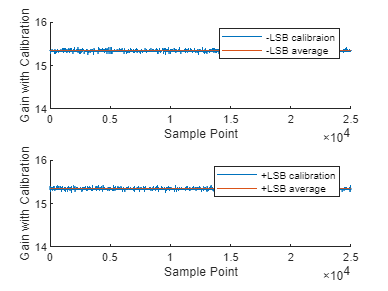



figure
subplot(2,1,1)
hold on;
plot(gain_min);
plot(ones([1,SAMPLE_POINT/4])*GAIN_MIN)
hold off;
xlim([0, SAMPLE_POINT/4]);
ylim([14,16]);
legend(["-LSB calibraion", ...
    "-LSB average"], ...
    'Location', 'northeast')
xlabel("Sample Point");
ylabel("Gain with Calibration");

subplot(2,1,2)
hold on;
plot(gain_plus);
plot(ones([1,SAMPLE_POINT/4])*GAIN_PLUS)
hold off;
xlim([0, SAMPLE_POINT/4]);
ylim([14,16]);

legend(["+LSB calibration",...
     "+LSB average"], ...
    'Location', 'northeast')
xlabel("Sample Point");
ylabel("Gain with Calibration");

function Gain = deltaGain(data_N4, num_itr)

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% target equation : 2G = ΔD2 + ΔD3/G + ΔD4/G^2
% f(x) = ΔD2 + ΔD3/G + ΔD4/G^2 - 2G
% f'(x) = -ΔD3/G^2 -2ΔD4/G^3 - 2
% G(i+1) = G(i) - f(G(i))/f'(G(i)) 
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


    Gain_length = length(data_N4)/2;
    delta_array_code = zeros(Gain_length, width(data_N4));
    Gain_resutls = zeros(Gain_length, num_itr);

    % data pre-process
    for i = 1:Gain_length
        delta_array_code(i,:) = data_N4(2*i-1,:) - data_N4(2*i,:);
    end

    % Newton Iteration
    Gain_resutls(:, 1) = 16;
    for j = 1:Gain_length
        for i = 2:num_itr
            Gain_temp = Gain_resutls(j,i-1);
            Gain_resutls(j,i) = Gain_temp - (f_G(delta_array_code(j,:), Gain_temp) ...
                            /fd_G(delta_array_code(j,:), Gain_temp));
        end
    end
    Gain = Gain_resutls(:, num_itr);
end


function f_G = f_G(D_array, G)      % f(x)
    f_G = D_array(1) + D_array(2)/G + D_array(3)/G^2 - 2*G;
end

function fd_G = fd_G(D_array, G)    % f'(x)
    fd_G = -D_array(2)/G^2 -2*(D_array(3)/G^3) - 2;
end 